## Parameter Analysis

uses the **minCOT.m** function to analyze parameters of interest:

- **forward speed (xdot_target)**

- **leg inertia (I)**

- **spring constant (k)**

- **damping constant (c)**

### **Forward Speed**

% add necessary paths
addpath('functions/multiOpt');
addpath('functions/sharedFuncs');
addpath('warmStartTemplates')

% some constants
k = 735;
c = 2.8;
I = 1.5e-4;

speeds = 1.5:0.25:3.5;
inertias = 1e-4:7.5e-5:4e-4;

running_COTs = [];
hopping_COTs = [];
next_guess = 0;

for I=inertias
    %runCOT_tmpRow = [];
    hopCOT_tmpRow = [];
    for speed=speeds
        % [runCOT, next_guess] = minCOT('r',speed, k, c, I, next_guess);
        % runCOT_tmpRow = [runCOT_tmpRow, runCOT];
        [hopCOT, next_guess] = minCOT('h',speed, k, c, I, next_guess);
        hopCOT_tmpRow = [hopCOT_tmpRow, hopCOT];
    end
    % running_COTs = [running_COTs; runCOT_tmpRow];
    hopping_COTs = [hopping_COTs; hopCOT_tmpRow];
end

Mode: h | Speed: 1.50 | k, c, I: 735 2.80 0.00010
using warm start template
Mode: h | Speed: 1.75 | k, c, I: 735 2.80 0.00010
Mode: h | Speed: 2.00 | k, c, I: 735 2.80 0.00010
Mode: h | Speed: 2.25 | k, c, I: 735 2.80 0.00010
Mode: h | Speed: 2.50 | k, c, I: 735 2.80 0.00010
Mode: h | Speed: 2.75 | k, c, I: 735 2.80 0.00010
Mode: h | Speed: 3.00 | k, c, I: 735 2.80 0.00010
Mode: h | Speed: 3.25 | k, c, I: 735 2.80 0.00010
Mode: h | Speed: 3.50 | k, c, I: 735 2.80 0.00010
Mode: h | Speed: 1.50 | k, c, I: 735 2.80 0.00017
Mode: h | Speed: 1.75 | k, c, I: 735 2.80 0.00017
Mode: h | Speed: 2.00 | k, c, I: 735 2.80 0.00017
Mode: h | Speed: 2.25 | k, c, I: 735 2.80 0.00017
Mode: h | Speed: 2.50 | k, c, I: 735 2.80 0.00017
Mode: h | Speed: 2.75 | k, c, I: 735 2.80 0.00017
Mode: h | Speed: 3.00 | k, c, I: 735 2.80 0.00017
Mode: h | Speed: 3.25 | k, c, I: 735 2.80 0.00017
Mode: h | Speed: 3.50 | k, c, I: 735 2.80 0.00017
Mode: h | Speed: 1.50 | k, c, I: 735 2.80 0.00025
Mode: h | Speed: 1.75 | 

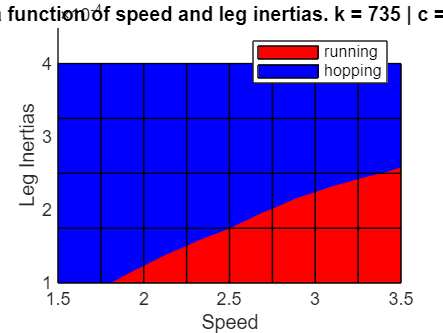

close all;
load inertia_speed_mesh_running;
load inertia_speed_mesh_hopping;
hold on;
surf(speeds, inertias, running_COTs, 'FaceColor', 'red');
surf(speeds, inertias, hopping_COTs,'FaceColor', 'blue');
xlabel("Speed");
ylabel("Leg Inertias");
zlabel("Cost");
title("Cost as a function of speed and leg inertias. " + ...
    "k = " + k/2 + " | c = " + c/2  + " | m = " + m);
legend("running", "hopping");
hold off;

rmpath('functions/multiOpt');
rmpath('functions/sharedFuncs');